%%%%%%%%-----------------DSP Experiment1_DFT-----------------%%%%%%%%
%Created by Yufeng Deng, Wednesday, Oct 18, 2023 at SEU

1.512点的DFT实现，自行设计数据考察运算结果是否正确，程序结束时给出总运行时间

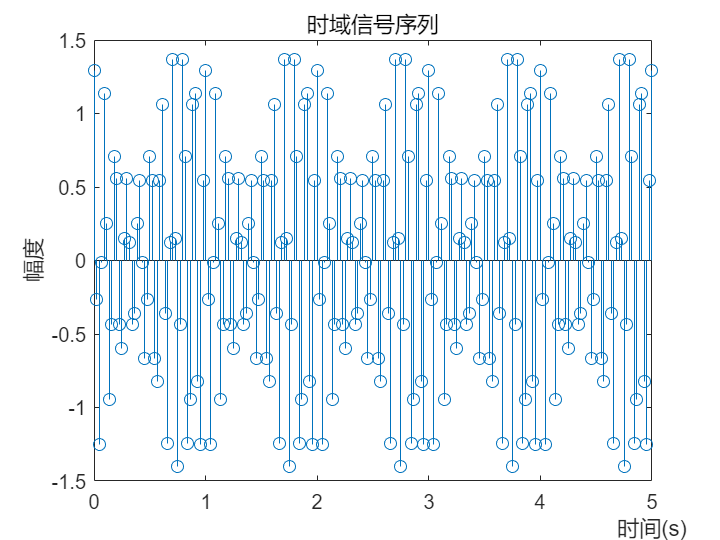

clc;clear;clf;
tic;
fs=44;          %采样频率（此处设定为模拟信号频率最大值的4倍）
Ts=1/fs;        %采样间隔
T=5;            %采样时长
k=0:Ts:T;       %采样序列横坐标
f1=10;          %模拟信号1频率（10Hz）
f2=11;          
w1=2*pi*f1;     %角频率（rad/s）
w2=2*pi*f2;
x=cos(w1*k)+0.5*cos(w2*k+0.3*pi);   %时域序列(10Hz叠加11Hz信号)
stem(k,x);
title('时域信号序列');
pos=axis;%取得当前坐标轴的范围，即[xmin xmax ymin ymax]
xlabel('时间(s)','position',[pos(2) 1.15*pos(3)]);%设置x轴标签位置
ylabel('幅度');

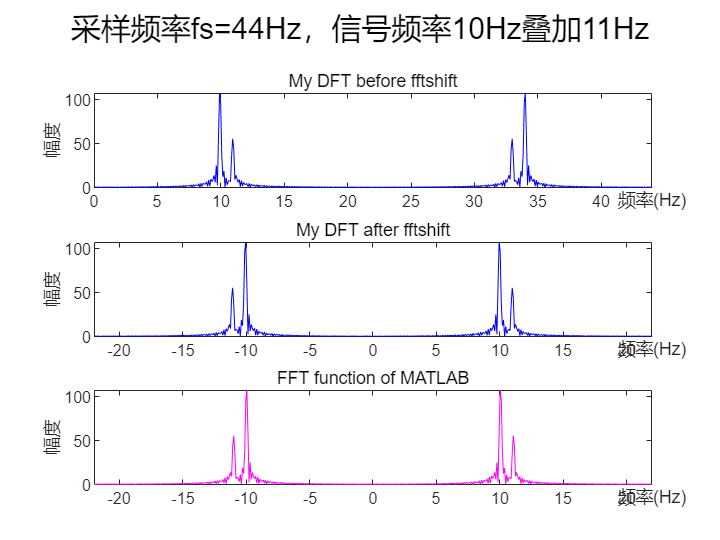


clf;
N=512;  %频域点数
%频域横坐标,由于频谱以fs为周期进行延拓，所以此处选择(0,fs)之间
f=linspace(0,fs,N);
%将频谱横坐标调整到(-fs/2,fs/2)之间，查看fftshift
fshift=linspace(-0.5*fs,0.5*fs,N);

X1=dft(x,N);        %自定义dft函数处理信号
X2=fftshift(X1);    %fftshift之后的频谱
FFT=fftshift(abs(fft(x,N)));    %MATLAB自带的fft函数

subplot(3,1,1)
plot(f,X1,'b');
xlim([0,fs]);
pos=axis;%取得当前坐标轴的范围，即[xmin xmax ymin ymax]
xlabel('频率(Hz)','position',[pos(2) 1.15*pos(3)]);%设置x轴标签位置
ylabel('幅度');title('My DFT before fftshift');

subplot(3,1,2)
plot(fshift,X2,'b');
xlim([-fs/2,fs/2]);
pos=axis;%取得当前坐标轴的范围，即[xmin xmax ymin ymax]
xlabel('频率(Hz)','position',[pos(2) 1.15*pos(3)]);%设置x轴标签位置
ylabel('幅度');title('My DFT after fftshift');

subplot(3,1,3)
plot(fshift,FFT,'m');
xlim([-fs/2,fs/2]);
pos=axis;%取得当前坐标轴的范围，即[xmin xmax ymin ymax]
xlabel('频率(Hz)','position',[pos(2) 1.15*pos(3)]);%设置x轴标签位置
ylabel('幅度');title('FFT function of MATLAB');

sgtitle('采样频率fs=44Hz，信号频率10Hz叠加11Hz');

toc;

历时 0.494956 秒。


2.采样时长不同对信号的DFT结果有何影响？采样时长非整周期对周期信号频谱的影响如何？

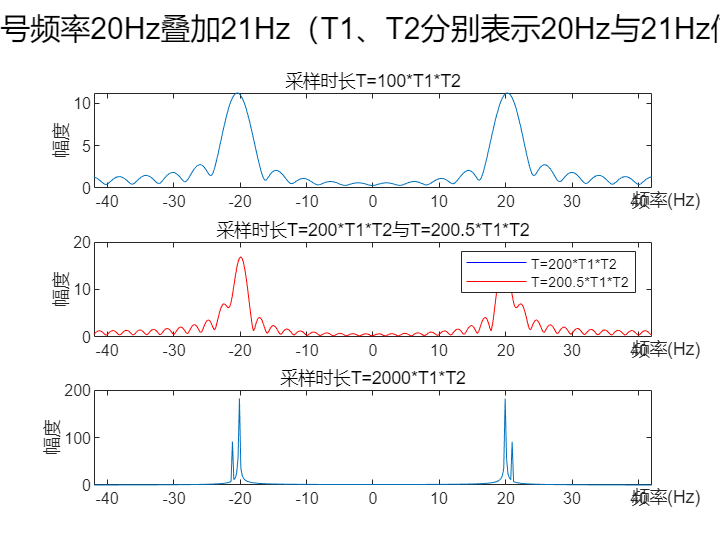

clear;clf;clc;
fs=84;          %采样频率（此处设定为模拟信号频率最大值的4倍）
Ts=1/fs;        %采样间隔

f1=20;f2=21;          %模拟信号频率（Hz）
w1=2*pi*f1;w2=2*pi*f2;     %角频率（rad/s）

T1=1/f1;T2=1/f2;

T=[100*T1*T2,200*T1*T2,200.5*T1*T2,2000*T1*T2];   %3种不同的采样时长
k1=0:Ts:T(1);       %采样序列横坐标
k2=0:Ts:T(2);
k3=0:Ts:T(3);
k4=0:Ts:T(4);

x1=cos(w1*k1)+0.5*cos(w2*k1+0.3*pi);    %时域序列(20Hz叠加21Hz信号)
x2=cos(w1*k2)+0.5*cos(w2*k2+0.3*pi);
x3=cos(w1*k3)+0.5*cos(w2*k3+0.3*pi);
x4=cos(w1*k4)+0.5*cos(w2*k4+0.3*pi);

N=400;  %频域点数
X1=fftshift(dft(x1,N));    %自定义dft函数处理信号
X2=fftshift(dft(x2,N));
X3=fftshift(dft(x3,N));
X4=fftshift(dft(x4,N));
fshift=linspace(-fs/2,fs/2,N);

subplot(3,1,1);
plot(fshift,X1);
xlim([-fs/2,fs/2]);
pos=axis;%取得当前坐标轴的范围，即[xmin xmax ymin ymax]
xlabel('频率(Hz)','position',[1.05*pos(2) 1.15*pos(3)]);%设置x轴标签位置
ylabel('幅度'),title('采样时长T=100*T1*T2');

subplot(3,1,2);
plot(fshift,X2,'b',fshift,X3,'r');
xlim([-fs/2,fs/2]);
xlabel('频率(Hz)','position',[1.05*pos(2) 1.15*pos(3)]);%设置x轴标签位置
ylabel('幅度'),title('采样时长T=200*T1*T2与T=200.5*T1*T2');
legend('T=200*T1*T2','T=200.5*T1*T2');

subplot(3,1,3);
plot(fshift,X4);
xlim([-fs/2,fs/2]);
xlabel('频率(Hz)','position',[1.05*pos(2) 1.15*pos(3)]);%设置x轴标签位置
ylabel('幅度'),title('采样时长T=2000*T1*T2');
sgtitle('fs=84Hz，信号频率20Hz叠加21Hz（T1、T2分别表示20Hz与21Hz信号的周期）');

3.频谱泄露相关理论证明，包含频谱泄露现象，窗函数选择与频谱泄露

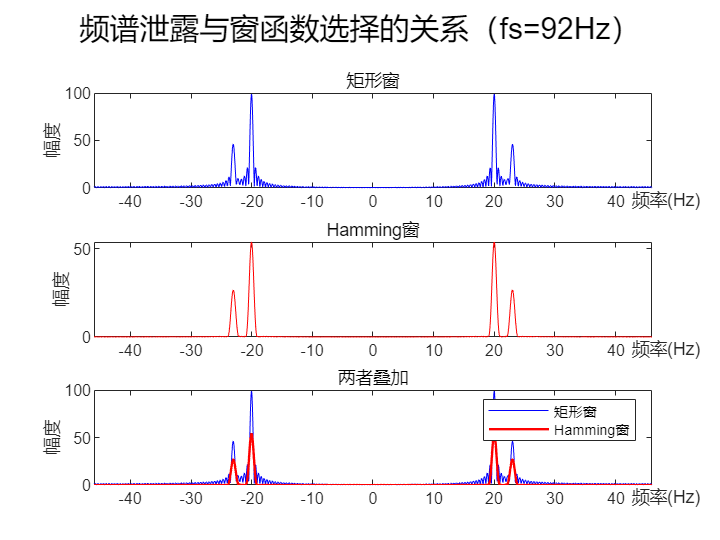

clear;clf;clc;
fs=92;          %采样频率（此处设定为模拟信号频率最大值的4倍）
Ts=1/fs;        %采样间隔
f1=20;f2=23;          %模拟信号频率（Hz）
w1=2*pi*f1;w2=2*pi*f2;     %角频率（rad/s）
T1=1/f1;T2=1/f2; %时域周期
T=1000*T1*T2;    %采样时长
L=fs*T+1;        %采样点数
k=0:Ts:T;        %采样序列横坐标
N=2048;          %dft点数
x=cos(w1*k)+0.5*cos(w2*k+0.3*pi);    %时域序列(20Hz叠加23Hz信号)
winHam=hamming(L)';         %Hamming窗
xHam=x.*winHam;
X=fftshift(dft(x,N));       %自定义dft函数处理信号
XHam=fftshift(dft(xHam,N)); %加hamming窗后的dft
fshift=linspace(-fs/2,fs/2,N);

subplot(3,1,1);
plot(fshift,X,'b');
xlim([-fs/2,fs/2]);
pos=axis;%取得当前坐标轴的范围，即[xmin xmax ymin ymax]
xlabel('频率(Hz)','position',[1.05*pos(2) 1.15*pos(3)]);%设置x轴标签位置
ylabel('幅度'),title('矩形窗');

subplot(3,1,2);
plot(fshift,XHam,'r');
xlim([-fs/2,fs/2]);
xlabel('频率(Hz)','position',[1.05*pos(2) 1.15*pos(3)]);%设置x轴标签位置
ylabel('幅度'),title('Hamming窗');

subplot(3,1,3);
plot(fshift,X,'b');
hold on
plot(fshift,XHam,'r','LineWidth',1.2);
xlim([-fs/2,fs/2]);
xlabel('频率(Hz)','position',[1.05*pos(2) 1.15*pos(3)]);%设置x轴标签位置
ylabel('幅度'),title('两者叠加');
legend('矩形窗','Hamming窗');
hold off
sgtitle('频谱泄露与窗函数选择的关系（fs=92Hz）')

4.两种插值方法，开展插值前后的频谱对比研究。

方法1：两个数据间插0

方法2：线性插值，插值数据等于前后数据和的一半

disp('------------------------Method1------------------------');

------------------------Method1------------------------


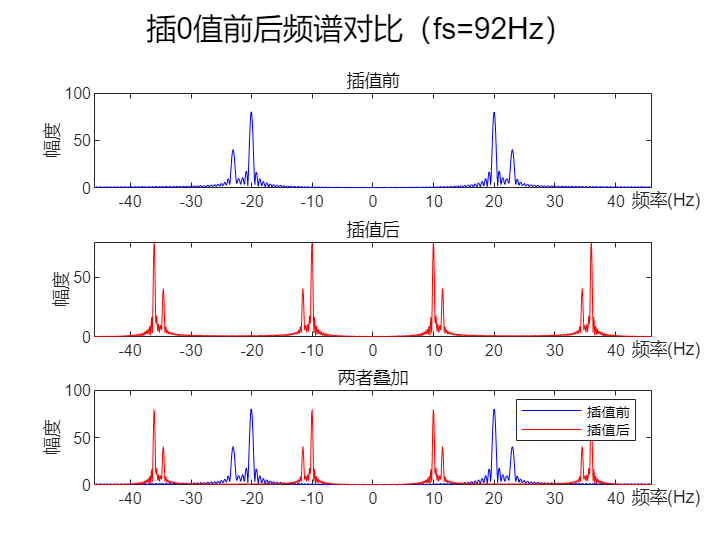

clear;clf;clc;
fs=92;          %采样频率（此处设定为模拟信号频率最大值的4倍）
Ts=1/fs;        %采样间隔
f1=20;f2=23;          %模拟信号频率（Hz）
w1=2*pi*f1;w2=2*pi*f2;     %角频率（rad/s）
T1=1/f1;T2=1/f2;
T=800*T1*T2;    %采样时长
L=fs*T+1;        %采样点数
k=0:Ts:T;        %采样序列横坐标
N=1024;          %dft点数
x=cos(w1*k)+0.5*cos(w2*k+0.3*pi);    %时域序列(20Hz叠加23Hz信号)
xInsert0=zeros(1,2*length(x));
j=1;
for k=1:2:length(xInsert0)-1
    xInsert0(k)=x(j);
    xInsert0(k+1)=0;    %插入0
    j=j+1;
end

X=fftshift(dft(x,N));       %自定义dft函数处理信号
XInsert0=fftshift(dft(xInsert0,N));
fshift=linspace(-fs/2,fs/2,N);

subplot(3,1,1);
plot(fshift,X,'b');
xlim([-fs/2,fs/2]);
pos=axis;%取得当前坐标轴的范围，即[xmin xmax ymin ymax]
xlabel('频率(Hz)','position',[1.05*pos(2) 1.15*pos(3)]);%设置x轴标签位置
ylabel('幅度'),title('插值前');

subplot(3,1,2);
plot(fshift,XInsert0,'r');
xlim([-fs/2,fs/2]);
xlabel('频率(Hz)','position',[1.05*pos(2) 1.15*pos(3)]);%设置x轴标签位置
ylabel('幅度'),title('插值后');

subplot(3,1,3);
plot(fshift,X,'b',fshift,XInsert0,'r');
xlim([-fs/2,fs/2]);
xlabel('频率(Hz)','position',[1.05*pos(2) 1.15*pos(3)]);%设置x轴标签位置
ylabel('幅度'),title('两者叠加');
legend('插值前','插值后');
sgtitle('插0值前后频谱对比（fs=92Hz）');

disp('------------------------Method2------------------------');

------------------------Method2------------------------


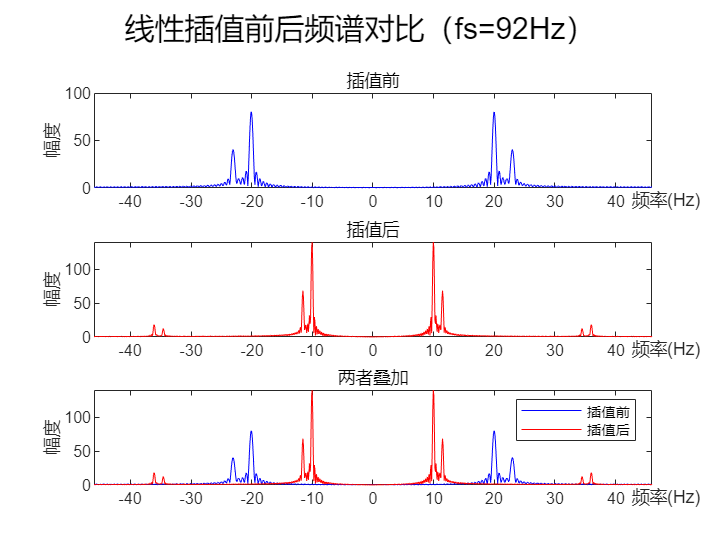

clf;
xInsertLinear=zeros(1,2*length(x));
j=1;
for k=1:2:length(xInsertLinear)-1
    xInsertLinear(k)=x(j);
    if(j==length(x))
        xInsertLinear(k+1)=x(j);%如果是最后一项的话，直接插原序列的最后一项
    end
    if(j<length(x))
        xInsertLinear(k+1)=(x(j)+x(j+1))/2; %线性插值
    end
    j=j+1;
end

X=fftshift(dft(x,N));       %自定义dft函数处理信号
XInsertLinear=fftshift(dft(xInsertLinear,N));
fshift=linspace(-fs/2,fs/2,N);
fshift

subplot(3,1,1);
plot(fshift,X,'b');
xlim([-fs/2,fs/2]);
pos=axis;%取得当前坐标轴的范围，即[xmin xmax ymin ymax]
xlabel('频率(Hz)','position',[1.05*pos(2) 1.15*pos(3)]);%设置x轴标签位置
ylabel('幅度'),title('插值前');

subplot(3,1,2);
plot(fshift,XInsertLinear,'r');
xlim([-fs/2,fs/2]);
xlabel('频率(Hz)','position',[1.05*pos(2) 1.15*pos(3)]);%设置x轴标签位置
ylabel('幅度'),title('插值后');

subplot(3,1,3);
plot(fshift,X,'b',fshift,XInsertLinear,'r');
xlim([-fs/2,fs/2]);
xlabel('频率(Hz)','position',[1.05*pos(2) 1.15*pos(3)]);%设置x轴标签位置
ylabel('幅度'),title('两者叠加');
legend('插值前','插值后');
sgtitle('线性插值前后频谱对比（fs=92Hz）');

function [X]=dft(x,N)
    x=[x,zeros(1,N-length(x))];%补零，使得X可以与x运算
    X=zeros(1,N);
    for m=1:N
        Xtemp=0;
        for k=1:N
            Xtemp=Xtemp+x(k)*exp(-2*pi*1i*k*m/N);
        end
        X(m)=abs(Xtemp);%X序列的第m项
    end
end